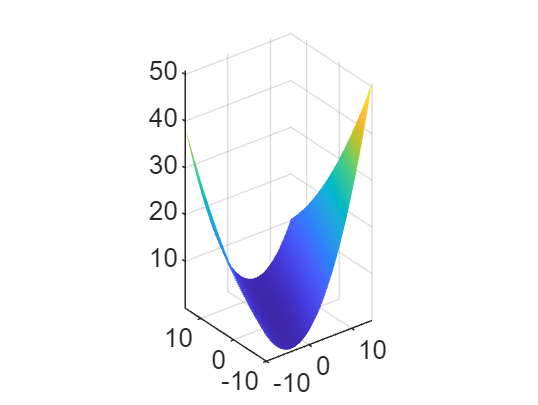

w0 = (-10:0.4:15)';
w1 = (-10:0.4:15)';

[W0,W1] = meshgrid(w0,w1);
f4 = 2*(W0 - 1).^2 + 3*(W1 - 2*W0).^2;
surf(W0,W1,0.01*f4,'EdgeColor', 'none')
axis equal

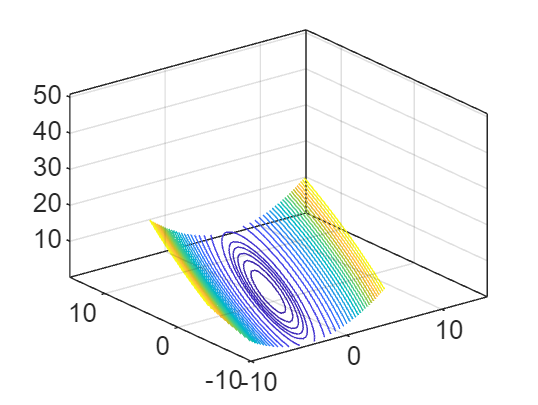


figure
contour3(W0,W1,0.01*f4,[0:0.1:0.5, 0.7:0.4:10])


% Initial guess
w = [0.3; -0.2];
% Leaning rate
eta = 0.0592;
for i=1:200
    df4dw = [4*(w(1) - 1) - 12*(w(2)-2*w(1));
                   6*(w(2) - 2*w(1))];
    w = w - eta*df4dw;
    disp(w)
end

   -0.1026
    0.0842

    0.3640
   -0.0186

   -0.0158
    0.2466

    0.4224
    0.1478

    0.0640
    0.3954

    0.4756
    0.3004

    0.1375
    0.5315

    0.5240
    0.4404

    0.2051
    0.6562

    0.5681
    0.5688

    0.2673
    0.7704

    0.6083
    0.6866

    0.3246
    0.8749

    0.6449
    0.7947

    0.3773
    0.9705

    0.6782
    0.8938

    0.4258
    1.0581

    0.7085
    0.9848

    0.4705
    1.1383

    0.7360
    1.0682

    0.5116
    1.2116

    0.7611
    1.1447

    0.5495
    1.2788

    0.7839
    1.2149

    0.5844
    1.3403

    0.8046
    1.2794

    0.6165
    1.3966

    0.8235
    1.3385

    0.6461
    1.4481

    0.8406
    1.3927

    0.6734
    1.4952

    0.8561
    1.4425

    0.6985
    1.5383

    0.8703
    1.4882

    0.7217
    1.5778

    0.8831
    1.5301

    0.7430
    1.6139

    0.8947
    1.5685

    0.7627
    1.6470

    0.9052
    1.6038

    0.7809
    1.6772

    0.9148
    1.6362

    0.7976
    1.7049

    0.9235
